# Introduction to Robotics

## Lab 8

### Shaaf Farooque, Mysha Zulfiqar

clc; clear all; close all;
arb = Arbotix('port', 'COM4', 'nservos', 5)

serPort COM4is in use.   Closing it.


i = 4

 
arb = 
Arbotix chain on serPort COM4 (open)
 5 servos in chain                  


arb.setpos(1,deg2rad(150))


arb.setpos(4,pi/1.5)

determineIntrinsics()

color_intrinsics = struct with fields:
     width: 1920
    height: 1080
       ppx: 951.5109
       ppy: 526.6981
        fx: 1.4053e+03
        fy: 1.4053e+03
     model: 0
    coeffs: [0 0 0 0 0]


depth_intrinsics = struct with fields:
     width: 640
    height: 480
       ppx: 308.9356
       ppy: 245.4494
        fx: 474.8976
        fy: 474.8976
     model: 2
    coeffs: [0.1457 0.0512 0.0038 0.0014 0.0663]


determineExtrinsics()

Tdc = struct with fields:
       rotation: [1.0000 -7.3491e-04 0.0013 7.4430e-04 1.0000 -0.0074 -0.0013 0.0074 1.0000]
    translation: [0.0257 -7.3326e-04 0.0044]


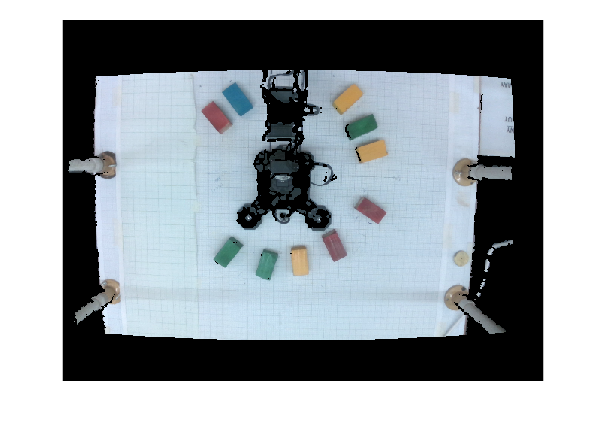

[img,ig] = depth_example();
imshow(img)

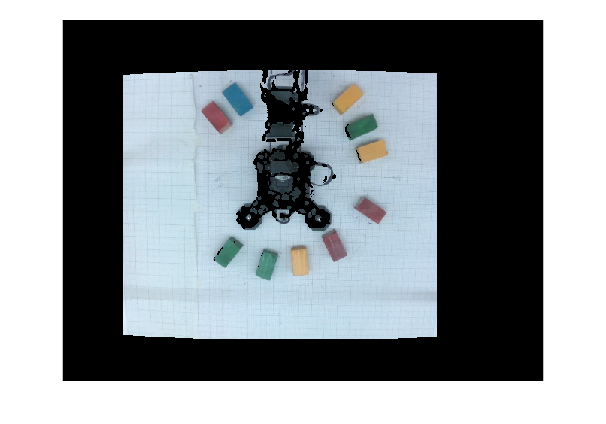

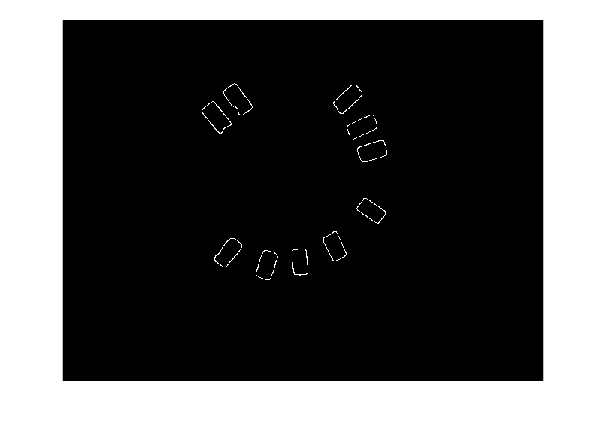

x = 10.2568

y = -12.3575

z = 5.4069

p_dest =    10.2568  -12.3575    9.4069


angles =     0.6928    1.9628   -1.3346    2.5133
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     0.6928    1.9628   -1.3346    2.5133
    0.6928    0.6431    1.3346    1.1639
         0         0         0         0
         0         0         0         0


angles =     0.6928    1.9628   -1.3346    2.5133
    0.6928    0.6431    1.3346    1.1639
    3.8344   -1.9628   -1.3346   -2.5133
         0         0         0         0


angles =     0.6928    1.9628   -1.3346    2.5133
    0.6928    0.6431    1.3346    1.1639
    3.8344   -1.9628   -1.3346   -2.5133
    3.8344   -0.6431   -1.3346   -1.1639


solution =     0.6928    0.6431    1.3346    1.1639


jointAngles =     0.9828    0.6431    1.3346    1.1639


angles =     0.6928    2.4654   -1.3643    2.0405
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     0.6928    2.4654   -1.3643    2.0405
    0.6928    1.1164    1.3643    0.6609
         0         0         0         0
         0         0         0         0


angles =     0.6928    2.4654   -1.3643    2.0405
    0.6928    1.1164    1.3643    0.6609
    3.8344   -2.4654   -1.3643   -2.0405
         0         0         0         0


angles =     0.6928    2.4654   -1.3643    2.0405
    0.6928    1.1164    1.3643    0.6609
    3.8344   -2.4654   -1.3643   -2.0405
    3.8344   -1.1164   -1.3643   -0.6609


solution =     0.6928    1.1164    1.3643    0.6609


angles =     1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles =     1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles =     1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution =     1.8925    0.5994    1.3452    1.1970


angles =     1.7042    2.3152   -1.4123    2.2386
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     1.7042    2.3152   -1.4123    2.2386
    1.7042    0.9191    1.4123    0.8103
         0         0         0         0
         0         0         0         0


angles =     1.7042    2.3152   -1.4123    2.2386
    1.7042    0.9191    1.4123    0.8103
   -1.4374   -2.3152   -1.4123   -2.2386
         0         0         0         0


angles =     1.7042    2.3152   -1.4123    2.2386
    1.7042    0.9191    1.4123    0.8103
   -1.4374   -2.3152   -1.4123   -2.2386
   -1.4374   -0.9191   -1.4123   -0.8103


solution =     1.7042    0.9191    1.4123    0.8103


x = 8.4197

y = 12.3929

z = 3.7321

p_dest =     8.4197   12.3929    7.7321


angles =     2.5448    2.1507   -1.5388    2.5297
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     2.5448    2.1507   -1.5388    2.5297
    2.5448    0.6302    1.5388    0.9727
         0         0         0         0
         0         0         0         0


angles =     2.5448    2.1507   -1.5388    2.5297
    2.5448    0.6302    1.5388    0.9727
   -0.5968   -2.1507   -1.5388   -2.5297
         0         0         0         0


angles =     2.5448    2.1507   -1.5388    2.5297
    2.5448    0.6302    1.5388    0.9727
   -0.5968   -2.1507   -1.5388   -2.5297
   -0.5968   -0.6302   -1.5388   -0.9727


solution =     2.5448    0.6302    1.5388    0.9727


jointAngles =     2.4948    0.6302    1.5388    0.9727


angles =     2.5448    2.6246   -1.4482    1.9651
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     2.5448    2.6246   -1.4482    1.9651
    2.5448    1.1932    1.4482    0.5003
         0         0         0         0
         0         0         0         0


angles =     2.5448    2.6246   -1.4482    1.9651
    2.5448    1.1932    1.4482    0.5003
   -0.5968   -2.6246   -1.4482   -1.9651
         0         0         0         0


angles =     2.5448    2.6246   -1.4482    1.9651
    2.5448    1.1932    1.4482    0.5003
   -0.5968   -2.6246   -1.4482   -1.9651
   -0.5968   -1.1932   -1.4482   -0.5003


solution =     2.5448    1.1932    1.4482    0.5003


angles =     1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles =     1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles =     1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution =     1.8925    0.5994    1.3452    1.1970


angles =     1.6997    2.3110   -1.4037    2.2343
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     1.6997    2.3110   -1.4037    2.2343
    1.6997    0.9233    1.4037    0.8147
         0         0         0         0
         0         0         0         0


angles =     1.6997    2.3110   -1.4037    2.2343
    1.6997    0.9233    1.4037    0.8147
   -1.4419   -2.3110   -1.4037   -2.2343
         0         0         0         0


angles =     1.6997    2.3110   -1.4037    2.2343
    1.6997    0.9233    1.4037    0.8147
   -1.4419   -2.3110   -1.4037   -2.2343
   -1.4419   -0.9233   -1.4037   -0.8147


solution =     1.6997    0.9233    1.4037    0.8147


x = 6.2423

y = -15.5140

z = 5.8069

p_dest =     6.2423  -15.5140    9.8069


angles =     0.3825    1.8924   -1.2162    2.4654
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles =     0.3825    1.8924   -1.2162    2.4654
    0.3825    0.6894    1.2162    1.2360
         0         0         0         0
         0         0         0         0


angles =     0.3825    1.8924   -1.2162    2.4654
    0.3825    0.6894    1.2162    1.2360
    3.5241   -1.8924   -1.2162   -2.4654
         0         0         0         0


angles =     0.3825    1.8924   -1.2162    2.4654
    0.3825    0.6894    1.2162    1.2360
    3.5241   -1.8924   -1.2162   -2.4654
    3.5241   -0.6894   -1.2162   -1.2360


solution =     0.3825    0.6894    1.2162    1.2360


jointAngles = 1×4
    0.6725    0.6894    1.2162    1.2360


angles = 4×4
    0.3825    2.3909   -1.2768    2.0275
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    0.3825    2.3909   -1.2768    2.0275
    0.3825    1.1281    1.2768    0.7367
         0         0         0         0
         0         0         0         0


angles = 4×4
    0.3825    2.3909   -1.2768    2.0275
    0.3825    1.1281    1.2768    0.7367
    3.5241   -2.3909   -1.2768   -2.0275
         0         0         0         0


angles = 4×4
    0.3825    2.3909   -1.2768    2.0275
    0.3825    1.1281    1.2768    0.7367
    3.5241   -2.3909   -1.2768   -2.0275
    3.5241   -1.1281   -1.2768   -0.7367


solution = 1×4
    0.3825    1.1281    1.2768    0.7367


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution = 1×4
    1.8925    0.5994    1.3452    1.1970


angles = 4×4
    1.7059    2.2818   -1.3847    2.2446
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.7059    2.2818   -1.3847    2.2446
    1.7059    0.9127    1.3847    0.8442
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.7059    2.2818   -1.3847    2.2446
    1.7059    0.9127    1.3847    0.8442
   -1.4357   -2.2818   -1.3847   -2.2446
         0         0         0         0


angles = 4×4
    1.7059    2.2818   -1.3847    2.2446
    1.7059    0.9127    1.3847    0.8442
   -1.4357   -2.2818   -1.3847   -2.2446
   -1.4357   -0.9127   -1.3847   -0.8442


solution = 1×4
    1.7059    0.9127    1.3847    0.8442


x = 1.3507

y = 14.8629

z = 3.2321

p_dest = 1×3
    1.3507   14.8629    7.2321


angles = 4×4
    3.0510    2.1918   -1.5576    2.5074
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.0510    2.1918   -1.5576    2.5074
    3.0510    0.6529    1.5576    0.9312
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.0510    2.1918   -1.5576    2.5074
    3.0510    0.6529    1.5576    0.9312
   -0.0906   -2.1918   -1.5576   -2.5074
         0         0         0         0


angles = 4×4
    3.0510    2.1918   -1.5576    2.5074
    3.0510    0.6529    1.5576    0.9312
   -0.0906   -2.1918   -1.5576   -2.5074
   -0.0906   -0.6529   -1.5576   -0.9312


solution = 1×4
   -0.0906   -0.6529   -1.5576   -0.9312


jointAngles = 1×4
   -0.1406   -0.6529   -1.5576   -0.9312


angles = 4×4
    3.0510    2.6470   -1.4312    1.9258
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.0510    2.6470   -1.4312    1.9258
    3.0510    1.2322    1.4312    0.4782
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.0510    2.6470   -1.4312    1.9258
    3.0510    1.2322    1.4312    0.4782
   -0.0906   -2.6470   -1.4312   -1.9258
         0         0         0         0


angles = 4×4
    3.0510    2.6470   -1.4312    1.9258
    3.0510    1.2322    1.4312    0.4782
   -0.0906   -2.6470   -1.4312   -1.9258
   -0.0906   -1.2322   -1.4312   -0.4782


solution = 1×4
   -0.0906   -1.2322   -1.4312   -0.4782


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution = 1×4
   -1.2490   -0.5994   -1.3452   -1.1970


angles = 4×4
    1.6950    2.3265   -1.4330    2.2481
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.6950    2.3265   -1.4330    2.2481
    1.6950    0.9100    1.4330    0.7986
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.6950    2.3265   -1.4330    2.2481
    1.6950    0.9100    1.4330    0.7986
   -1.4466   -2.3265   -1.4330   -2.2481
         0         0         0         0


angles = 4×4
    1.6950    2.3265   -1.4330    2.2481
    1.6950    0.9100    1.4330    0.7986
   -1.4466   -2.3265   -1.4330   -2.2481
   -1.4466   -0.9100   -1.4330   -0.7986


solution = 1×4
   -1.4466   -0.9100   -1.4330   -0.7986


x = -4.9760

y = 14.3099

z = 3.1821

p_dest = 1×3
   -4.9760   14.3099    7.1821


angles = 4×4
    3.4762    2.1828   -1.5283    2.4870
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.4762    2.1828   -1.5283    2.4870
    3.4762    0.6727    1.5283    0.9407
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.4762    2.1828   -1.5283    2.4870
    3.4762    0.6727    1.5283    0.9407
    0.3347   -2.1828   -1.5283   -2.4870
         0         0         0         0


angles = 4×4
    3.4762    2.1828   -1.5283    2.4870
    3.4762    0.6727    1.5283    0.9407
    0.3347   -2.1828   -1.5283   -2.4870
    0.3347   -0.6727   -1.5283   -0.9407


solution = 1×4
    0.3347   -0.6727   -1.5283   -0.9407


jointAngles = 1×4
    0.0547   -0.6727   -1.5283   -0.9407


angles = 4×4
    3.4762    2.6285   -1.3980    1.9111
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.4762    2.6285   -1.3980    1.9111
    3.4762    1.2464    1.3980    0.4972
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.4762    2.6285   -1.3980    1.9111
    3.4762    1.2464    1.3980    0.4972
    0.3347   -2.6285   -1.3980   -1.9111
         0         0         0         0


angles = 4×4
    3.4762    2.6285   -1.3980    1.9111
    3.4762    1.2464    1.3980    0.4972
    0.3347   -2.6285   -1.3980   -1.9111
    0.3347   -1.2464   -1.3980   -0.4972


solution = 1×4
    0.3347   -1.2464   -1.3980   -0.4972


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution = 1×4
   -1.2490   -0.5994   -1.3452   -1.1970


angles = 4×4
    1.6946    2.3278   -1.4395    2.2533
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.6946    2.3278   -1.4395    2.2533
    1.6946    0.9049    1.4395    0.7973
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.6946    2.3278   -1.4395    2.2533
    1.6946    0.9049    1.4395    0.7973
   -1.4470   -2.3278   -1.4395   -2.2533
         0         0         0         0


angles = 4×4
    1.6946    2.3278   -1.4395    2.2533
    1.6946    0.9049    1.4395    0.7973
   -1.4470   -2.3278   -1.4395   -2.2533
   -1.4470   -0.9049   -1.4395   -0.7973


solution = 1×4
   -1.4470   -0.9049   -1.4395   -0.7973


x = -11.4217

y = 11.3159

z = 3.4571

p_dest = 1×3
  -11.4217   11.3159    7.4571


angles = 4×4
    3.9316    2.1076   -1.3927    2.4267
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.9316    2.1076   -1.3927    2.4267
    3.9316    0.7307    1.3927    1.0182
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.9316    2.1076   -1.3927    2.4267
    3.9316    0.7307    1.3927    1.0182
    0.7901   -2.1076   -1.3927   -2.4267
         0         0         0         0


angles = 4×4
    3.9316    2.1076   -1.3927    2.4267
    3.9316    0.7307    1.3927    1.0182
    0.7901   -2.1076   -1.3927   -2.4267
    0.7901   -0.7307   -1.3927   -1.0182


solution = 1×4
    0.7901   -0.7307   -1.3927   -1.0182


jointAngles = 1×4
    0.5101   -0.7307   -1.3927   -1.0182


angles = 4×4
    3.9316    2.5356   -1.2797    1.8857
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.9316    2.5356   -1.2797    1.8857
    3.9316    1.2700    1.2797    0.5919
         0         0         0         0
         0         0         0         0


angles = 4×4
    3.9316    2.5356   -1.2797    1.8857
    3.9316    1.2700    1.2797    0.5919
    0.7901   -2.5356   -1.2797   -1.8857
         0         0         0         0


angles = 4×4
    3.9316    2.5356   -1.2797    1.8857
    3.9316    1.2700    1.2797    0.5919
    0.7901   -2.5356   -1.2797   -1.8857
    0.7901   -1.2700   -1.2797   -0.5919


solution = 1×4
    0.7901   -1.2700   -1.2797   -0.5919


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution = 1×4
   -1.2490   -0.5994   -1.3452   -1.1970


angles = 4×4
    1.7050    2.3215   -1.4328    2.2529
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.7050    2.3215   -1.4328    2.2529
    1.7050    0.9051    1.4328    0.8037
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.7050    2.3215   -1.4328    2.2529
    1.7050    0.9051    1.4328    0.8037
   -1.4366   -2.3215   -1.4328   -2.2529
         0         0         0         0


angles = 4×4
    1.7050    2.3215   -1.4328    2.2529
    1.7050    0.9051    1.4328    0.8037
   -1.4366   -2.3215   -1.4328   -2.2529
   -1.4366   -0.9051   -1.4328   -0.8037


solution = 1×4
   -1.4366   -0.9051   -1.4328   -0.8037


x = -13.5392

y = -15.6084

z = 5.4569

p_dest = 1×3
  -13.5392  -15.6084    9.4569


angles = 4×4
   -0.7145    1.4344   -0.1536    1.8608
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
   -0.7145    1.4344   -0.1536    1.8608
   -0.7145    1.2823    0.1536    1.7057
         0         0         0         0
         0         0         0         0


angles = 4×4
   -0.7145    1.4344   -0.1536    1.8608
   -0.7145    1.2823    0.1536    1.7057
    2.4271   -1.4344   -0.1536   -1.8608
         0         0         0         0


angles = 4×4
   -0.7145    1.4344   -0.1536    1.8608
   -0.7145    1.2823    0.1536    1.7057
    2.4271   -1.4344   -0.1536   -1.8608
    2.4271   -1.2823   -0.1536   -1.7057


solution = 1×4
   -0.7145    1.2823    0.1536    1.7057


jointAngles = 1×4
   -0.9045    1.2823    0.1536    1.7057


angles = 4×4
   -0.7145    1.8886   -0.2988    1.5518
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
   -0.7145    1.8886   -0.2988    1.5518
   -0.7145    1.5926    0.2988    1.2502
         0         0         0         0
         0         0         0         0


angles = 4×4
   -0.7145    1.8886   -0.2988    1.5518
   -0.7145    1.5926    0.2988    1.2502
    2.4271   -1.8886   -0.2988   -1.5518
         0         0         0         0


angles = 4×4
   -0.7145    1.8886   -0.2988    1.5518
   -0.7145    1.5926    0.2988    1.2502
    2.4271   -1.8886   -0.2988   -1.5518
    2.4271   -1.5926   -0.2988   -1.2502


solution = 1×4
   -0.7145    1.5926    0.2988    1.2502


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution = 1×4
    1.8925    0.5994    1.3452    1.1970


angles = 4×4
    1.6996    2.3057   -1.4069    2.2428
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.6996    2.3057   -1.4069    2.2428
    1.6996    0.9148    1.4069    0.8199
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.6996    2.3057   -1.4069    2.2428
    1.6996    0.9148    1.4069    0.8199
   -1.4420   -2.3057   -1.4069   -2.2428
         0         0         0         0


angles = 4×4
    1.6996    2.3057   -1.4069    2.2428
    1.6996    0.9148    1.4069    0.8199
   -1.4420   -2.3057   -1.4069   -2.2428
   -1.4420   -0.9148   -1.4069   -0.8199


solution = 1×4
    1.6996    0.9148    1.4069    0.8199


x = -16.1473

y = -10.6085

z = 5.3069

p_dest = 1×3
  -16.1473  -10.6085    9.3069


angles = 4×4
   -0.9895    1.7140   -0.7324    2.1599
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
   -0.9895    1.7140   -0.7324    2.1599
   -0.9895    0.9889    0.7324    1.4203
         0         0         0         0
         0         0         0         0


angles = 4×4
   -0.9895    1.7140   -0.7324    2.1599
   -0.9895    0.9889    0.7324    1.4203
    2.1521   -1.7140   -0.7324   -2.1599
         0         0         0         0


angles = 4×4
   -0.9895    1.7140   -0.7324    2.1599
   -0.9895    0.9889    0.7324    1.4203
    2.1521   -1.7140   -0.7324   -2.1599
    2.1521   -0.9889   -0.7324   -1.4203


solution = 1×4
   -0.9895    0.9889    0.7324    1.4203


jointAngles = 1×4
   -1.1795    0.9889    0.7324    1.4203


angles = 4×4
   -0.9895    2.1381   -0.7645    1.7680
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
   -0.9895    2.1381   -0.7645    1.7680
   -0.9895    1.3812    0.7645    0.9959
         0         0         0         0
         0         0         0         0


angles = 4×4
   -0.9895    2.1381   -0.7645    1.7680
   -0.9895    1.3812    0.7645    0.9959
    2.1521   -2.1381   -0.7645   -1.7680
         0         0         0         0


angles = 4×4
   -0.9895    2.1381   -0.7645    1.7680
   -0.9895    1.3812    0.7645    0.9959
    2.1521   -2.1381   -0.7645   -1.7680
    2.1521   -1.3812   -0.7645   -0.9959


solution = 1×4
   -0.9895    1.3812    0.7645    0.9959


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution = 1×4
    1.8925    0.5994    1.3452    1.1970


angles = 4×4
    1.7001    2.2977   -1.3970    2.2409
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.7001    2.2977   -1.3970    2.2409
    1.7001    0.9166    1.3970    0.8280
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.7001    2.2977   -1.3970    2.2409
    1.7001    0.9166    1.3970    0.8280
   -1.4414   -2.2977   -1.3970   -2.2409
         0         0         0         0


angles = 4×4
    1.7001    2.2977   -1.3970    2.2409
    1.7001    0.9166    1.3970    0.8280
   -1.4414   -2.2977   -1.3970   -2.2409
   -1.4414   -0.9166   -1.3970   -0.8280


solution = 1×4
    1.7001    0.9166    1.3970    0.8280


x = -18.1902

y = 4.5696

z = 3.9446

p_dest = 1×3
  -18.1902    4.5696    7.9446


angles = 4×4
    4.4663    1.8716   -0.9224    2.1924
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    4.4663    1.8716   -0.9224    2.1924
    4.4663    0.9586    0.9224    1.2606
         0         0         0         0
         0         0         0         0


angles = 4×4
    4.4663    1.8716   -0.9224    2.1924
    4.4663    0.9586    0.9224    1.2606
    1.3247   -1.8716   -0.9224   -2.1924
         0         0         0         0


angles = 4×4
    4.4663    1.8716   -0.9224    2.1924
    4.4663    0.9586    0.9224    1.2606
    1.3247   -1.8716   -0.9224   -2.1924
    1.3247   -0.9586   -0.9224   -1.2606


solution = 1×4
    1.3247   -0.9586   -0.9224   -1.2606


jointAngles = 1×4
    1.0447   -0.9586   -0.9224   -1.2606


angles = 4×4
    4.4663    2.2421   -0.8243    1.7238
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    4.4663    2.2421   -0.8243    1.7238
    4.4663    1.4260    0.8243    0.8912
         0         0         0         0
         0         0         0         0


angles = 4×4
    4.4663    2.2421   -0.8243    1.7238
    4.4663    1.4260    0.8243    0.8912
    1.3247   -2.2421   -0.8243   -1.7238
         0         0         0         0


angles = 4×4
    4.4663    2.2421   -0.8243    1.7238
    4.4663    1.4260    0.8243    0.8912
    1.3247   -2.2421   -0.8243   -1.7238
    1.3247   -1.4260   -0.8243   -0.8912


solution = 1×4
    1.3247   -1.4260   -0.8243   -0.8912


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution = 1×4
   -1.2490   -0.5994   -1.3452   -1.1970


angles = 4×4
    1.6903    2.3269   -1.4274    2.2421
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.6903    2.3269   -1.4274    2.2421
    1.6903    0.9158    1.4274    0.7984
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.6903    2.3269   -1.4274    2.2421
    1.6903    0.9158    1.4274    0.7984
   -1.4513   -2.3269   -1.4274   -2.2421
         0         0         0         0


angles = 4×4
    1.6903    2.3269   -1.4274    2.2421
    1.6903    0.9158    1.4274    0.7984
   -1.4513   -2.3269   -1.4274   -2.2421
   -1.4513   -0.9158   -1.4274   -0.7984


solution = 1×4
   -1.4513   -0.9158   -1.4274   -0.7984


x = -17.9706

y = -6.2819

z = 5.0444

p_dest = 1×3
  -17.9706   -6.2819    9.0444


angles = 4×4
   -1.2345    1.7652   -0.8156    2.1920
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
   -1.2345    1.7652   -0.8156    2.1920
   -1.2345    0.9578    0.8156    1.3683
         0         0         0         0
         0         0         0         0


angles = 4×4
   -1.2345    1.7652   -0.8156    2.1920
   -1.2345    0.9578    0.8156    1.3683
    1.9071   -1.7652   -0.8156   -2.1920
         0         0         0         0


angles = 4×4
   -1.2345    1.7652   -0.8156    2.1920
   -1.2345    0.9578    0.8156    1.3683
    1.9071   -1.7652   -0.8156   -2.1920
    1.9071   -0.9578   -0.8156   -1.3683


solution = 1×4
   -1.2345    0.9578    0.8156    1.3683


jointAngles = 1×4
   -1.4245    0.9578    0.8156    1.3683


angles = 4×4
   -1.2345    2.1815   -0.8199    1.7800
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
   -1.2345    2.1815   -0.8199    1.7800
   -1.2345    1.3698    0.8199    0.9519
         0         0         0         0
         0         0         0         0


angles = 4×4
   -1.2345    2.1815   -0.8199    1.7800
   -1.2345    1.3698    0.8199    0.9519
    1.9071   -2.1815   -0.8199   -1.7800
         0         0         0         0


angles = 4×4
   -1.2345    2.1815   -0.8199    1.7800
   -1.2345    1.3698    0.8199    0.9519
    1.9071   -2.1815   -0.8199   -1.7800
    1.9071   -1.3698   -0.8199   -0.9519


solution = 1×4
   -1.2345    1.3698    0.8199    0.9519


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
         0         0         0         0


angles = 4×4
    1.8925    1.9296   -1.3452    2.5572
    1.8925    0.5994    1.3452    1.1970
   -1.2490   -1.9296   -1.3452   -2.5572
   -1.2490   -0.5994   -1.3452   -1.1970


solution = 1×4
    1.8925    0.5994    1.3452    1.1970


angles = 4×4
    1.7010    2.2809   -1.3831    2.2438
         0         0         0         0
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.7010    2.2809   -1.3831    2.2438
    1.7010    0.9134    1.3831    0.8450
         0         0         0         0
         0         0         0         0


angles = 4×4
    1.7010    2.2809   -1.3831    2.2438
    1.7010    0.9134    1.3831    0.8450
   -1.4406   -2.2809   -1.3831   -2.2438
         0         0         0         0


angles = 4×4
    1.7010    2.2809   -1.3831    2.2438
    1.7010    0.9134    1.3831    0.8450
   -1.4406   -2.2809   -1.3831   -2.2438
   -1.4406   -0.9134   -1.3831   -0.8450


solution = 1×4
    1.7010    0.9134    1.3831    0.8450


armDemo(arb); 

function armDemo(arb)
    placed = 1;
    STATE = 1;
    global focalLength principalPoint
    focalLength = [1.4053e+03, 1.4053e+03]; 
    principalPoint = [951.5109, 526.6981];
    while STATE ~= 8
        switch STATE
            case 1
                homePosition(arb)
                STATE = STATE + 1;
                pause(4)
            case 2
                [targets, howMany] = findTargets();
                STATE = STATE + 1;
            case 3
                if placed <= howMany
                    prev = goToTarget(targets(placed), arb);
                    STATE = STATE + 1;
                    pause(5)
                end
            case 4
                pickTarget(arb, prev);
                STATE = STATE + 1;
                pause(4)
            case 5
                goToPlace(arb);
                STATE = STATE + 1;
                pause(6)
            case 6
                place(arb);
                placed = placed + 1;
                STATE = STATE + 1;
                pause(3)
            case 7
                if placed > howMany
                    STATE = 8;
                    homePosition(arb);
                else
                    homePosition(arb);
                    STATE = 3;
                    pause(3)
                end
            otherwise
                STATE = 8;

        end
    end
end

function homePosition(arb)
    arb.setpos([0, pi/3, pi/12, pi/2, 0], [100 100 100 100 100]);
end
function [targets, howMany] = findTargets()
    global img ig BW
    [img,ig] = depth_example();
    img(:, 1:80, :) = 0;
    img(:, 500:640, :) = 0;
    img(425:480, :, :) = 0;
    img(1:65, :, :) = 0;
    figure;
    imshow(img);
    [blueMask, ~] = createBlueMask(img);
    [yellowMask, ~] = createYellowMask(img);
    [redMask, ~] = createRedMask(img);
    [greenMask, ~] = createGreenMask(img);
    BW = blueMask | redMask | yellowMask | greenMask;
    BW = edge(BW, 'Canny');
    figure;
    imshow(BW)
    targets = regionprops(BW, "BoundingBox");
    howMany = length(targets);
end
function prev = goToTarget(target, arb)
    global BW ig principalPoint pose_obj
    cube_mask = false(size(BW));
    cube_mask(round(target.BoundingBox(2)):round(target.BoundingBox(2) + target.BoundingBox(4)), ...
    round(target.BoundingBox(1)):round(target.BoundingBox(1) + target.BoundingBox(3))) = true;
    cubes = cube_mask & BW;
    stats = regionprops(cubes, 'Centroid');
    object_center = stats.Centroid;
    row = round(object_center(2));
    col = round(object_center(1));
    depth = ig(row, col);
    
    [x,y,z] = pixelToCameraCoords(col, row, depth, principalPoint(1), principalPoint(2));
    
    x = (-x- 6) + 1 
    y = (y + 1.9)  - 0.1 
    z = 70 - z
    pose_obj = [x, y, z];
    p_dest = pose_obj + [0 0 4]
    currentPos = arb.getpos();
    jointAngles = findOptimalSolution(p_dest, currentPos(1:4))
    %jointAngles = jointAngles - [pi/9.5 0 0 0];
    prev = jointAngles;
    arb.setpos([jointAngles 0], [60 60 60 60 60]);
end

function pickTarget(arb, prev)
    global pose_obj
    p_dest = pose_obj - [0 0 4];
    currentPos = arb.getpos();
    jointAngles = findOptimalSolution(p_dest, currentPos(1:4));
    %jointAngles = jointAngles - [0 0 0 -0.3];
    arb.setpos([jointAngles 0], [60 60 60 60 60])
    x = p_dest(1);
    y = p_dest(2);
    pause(3)
    if x<0 && y<0
        jointAngles = jointAngles - [0 0 0 -0.3];
        arb.setpos([jointAngles 0], [60 60 60 60 60])
        pause(1)
    end
    temp = arb.getpos();
    arb.setpos([temp(1:4), 1.2], [60 60 60 60 60])
    pause(2)
    arb.setpos([prev 1.2], [60 60 60 60 60])
end

function goToPlace(arb)
    p_dest = [15 5 10];
    currentPos = arb.getpos();
    jointAngles = findOptimalSolution(p_dest, currentPos(1:4));
    %jointAngles = jointAngles - [0 0 0 -0.3];
    arb.setpos([jointAngles 1.2], [60 60 60 60 60])
    pause(3)
end

function place(arb)
    currentPos = arb.getpos();
    [x, y, z, ~] = pincherFK(currentPos);
    pose_obj = [x, y, z];
    p_dest = pose_obj - [-1 2 5];
    jointAngles = findOptimalSolution(p_dest, currentPos(1:4));
    %jointAngles = jointAngles - [0 0 0 -0.3];
    arb.setpos([jointAngles currentPos(5)], [60 60 60 60 60])
    pause(3)
    temp = arb.getpos();
    arb.setpos([temp(1:4), 0], [60 60 60 60 60])
    pause(3)
    arb.setpos([currentPos(1:4) 0], [60 60 60 60 60])
end

function [X_cm, Y_cm, Z_cm] = pixelToCameraCoords(u, v, Z_m, cx, cy)
    u0 = cx * (640/1920);
    v0 = cy * (480/1080);

    X = ((u - u0) * Z_m) / 474.8976;
    Y = ((v - v0) * Z_m) / 474.8976;

    X_cm = X * 100;
    Y_cm = Y * 100;
    Z_cm = Z_m * 100;
end

% Kinematics  Helper Functions
function vs = skew(v)
    vs = [0 -v(3) v(2);
          v(3) 0 -v(1);
         -v(2) v(1) 0];
end


function T = exp(S, theta)
    w_skew = skew(S(1:3)/norm(S(1:3)));
    exp_w = eye(3) + w_skew*sin(theta) + w_skew^2*(1-cos(theta));
    G = eye(3)*theta + (1-cos(theta))*w_skew+(theta-sin(theta))*w_skew^2;
    T = [exp_w, G*S(4:6);
         zeros(1,3), 1];
end

function [S1, S2, S3, S4, Tsb] = getTsb()
    l_1=10;
    l_2=4.5;
    l_3=10.7;
    l_4=10.5;
    w1 = [0;0;1];
    q1 = [0;0;l_1];
    S1 = [w1;cross(-w1,q1)];
    
    w2 = [1;0;0];
    q2 = [0;0;l_1+l_2];
    S2 = [w2;cross(-w2,q2)];
    
    w3 = [1;0;0];
    q3 = [0;0;l_1+l_2+l_3];
    S3 = [w3;cross(-w3,q3)];
    
    w4 = [1;0;0];
    q4 = [0;0;l_1+l_2+l_3+l_4];
    S4 = [w4;cross(-w4,q4)];

    syms theta_1 theta_2 theta_3 theta_4
    Tsb = exp(S1,theta_1)*exp(S2,theta_2)*exp(S3,theta_3)*exp(S4,theta_4);
end


function zeroConfig= getZeroConf()
    l_1=10;
    l_2=4.5;
    l_3=10.7;
    l_4=10.5;
    l_5=9.5;
    zeroConfig = [1 0 0 0;
         0 1 0 0;
         0 0 1 l_1 + l_2 + l_3 + l_4 + l_5;
         0 0 0 1];
end
function [x,y,z,R] = pincherFK(jointAngles)
    M = getZeroConf();
    syms theta_1 theta_2 theta_3 theta_4
    [~, ~, ~, ~, Tsb] = getTsb();
    T = double(subs(Tsb,[theta_1 theta_2 theta_3 theta_4],jointAngles(1:4))*M);
    x = T(1,4);
    y = T(2,4);
    z = T(3,4);
    R = T(1:3, 1:3);
end

function angles = findJointAngles(x,y,z,phi)
    angles = zeros(4,4);
    l_1=10;
    l_2=4.5;
    l_3=10.7;
    l_4=10.5;
    l_5=9.5;

    theta1_1 = mod(atan2(y,x) + pi, 2*pi) - pi;
    theta1_2 = mod(atan2(y,x) +pi + pi, 2*pi) - pi;
    
    r = sqrt(x^2 + y^2);
    s = z - (l_1+l_2);

    r_ = r - l_5*cos(phi);
    s_ = s - l_5*sin(phi);

    D = ((r_*r_) + (s_*s_) - l_3^2 - l_4^2)/(2*l_3*l_4);

    num = sqrt(1-D*D);

    theta3_1 = mod(atan2((num),D) + pi, 2*pi) - pi;
    theta3_2 = mod(atan2(-(num),D) + pi, 2*pi) - pi;

    theta2_1 = mod(atan2(s_,r_) - atan2(l_4*sin(theta3_1), l_3 + l_4*cos(theta3_1)) + pi, 2*pi) - pi;
    theta2_2 = mod(atan2(s_,r_) - atan2(l_4*sin(theta3_2), l_3 + l_4*cos(theta3_2)) + pi, 2*pi) - pi;

    theta4_1 = mod((phi - theta2_1 - theta3_1) + pi, 2*pi) - pi;
    theta4_2 = mod((phi - theta2_2 - theta3_2)  + pi, 2*pi) - pi;
    
    angles(1,:) = [theta1_1+pi/2 -theta2_1+pi/2  -theta3_1 -theta4_1]
    angles(2,:) = [theta1_1+pi/2 -theta2_2+pi/2  -theta3_2 -theta4_2]
    angles(3,:) = [theta1_2+pi/2 -(-theta2_1+pi)+pi/2 -theta3_1 theta4_1]
    angles(4,:) = [theta1_2+pi/2 -(-theta2_2+pi)+pi/2 theta3_2 theta4_2]
    % angles = mod(angles + pi, 2*pi) - pi;

end


function solution = findOptimalSolution(desiredPos, currentPos)
     x = desiredPos(1);
     y = desiredPos(2); 
     z = desiredPos(3);
     phi = -pi/2;
     

    solutions = findJointAngles(x, y, z, phi);
    
    B = cellfun(@checkJointLimits, num2cell(solutions, 2), 'UniformOutput', false);
    B = cell2mat(B);  % B is now n_solutions × 4 logical matrix
    
    % Identify solutions where ALL joints are within limits
    valid_solutions_mask = all(B, 2);  % True only if all joints in a row are true
    
    % Keep only valid solutions (original joint angles)
    valid_solutions = solutions(valid_solutions_mask, :);
    
    % If no valid solutions, return empty or handle error
    if isempty(valid_solutions)
        solution = [];  % Or throw an error/warning as needed
        return;
    end
    
    % Absolute errors for all joints of all valid solutions
    delta = abs(valid_solutions - currentPos(1, 1:4));
    
    s = sum(delta, 2);
    
    % Find the solution with the minimum total error
    [~, idx] = min(s);
    solution = valid_solutions(idx, :) % Return the actual joint angles

    if x <0 && y>0
        solution = valid_solutions(idx, :) - [0.28 0 0 0];
    end

     if x > 0 && y>0
        solution = valid_solutions(idx, :) - [0.05 0 0 0];
     end
    if x >0 && y<0
        solution = valid_solutions(idx, :) + [0.29 0 0 0];
    end

    if x <0 && y<0
        solution = valid_solutions(idx, :) - [0.19 0 0 0];
    end

end

function isValid = checkJointLimits(jointAngles)
    % joint angle limits in radians (-150 to 150 degrees)
    thetaLimits = [-150*pi/180, 150*pi/180]; % Convert degrees to radians
    
    % Check if all joint angles are within limits
    isValid = all(jointAngles >= thetaLimits(1) & jointAngles <= thetaLimits(2));
end